# **Create a mass spectrum and define ranges**

This live script will guide you through the first steps of generation of a mass spectrum and the definition of ranges of an atom probe data set with this toolbox.

First of all, the colorScheme and the isotopeTable_naturalAbundances need to be loaded. The colorScheme provides a color code for all elements of the periodic table and common molecules. In isotopeTable_naturalAbundances, all isotopes of the elements, their weight, natrual abundance, and atom density are given. Subsequently, a *.pos file can be loaded. A window will pop-up and you can choose your file. If you want to load an *.epos file, be aware to change the selection in the selection window (buttom right) to *.epos. 

load isotopeTable_naturalAbundances.mat
load colorScheme.mat
pos = posToTable;

file R56_01769-v01.pos loaded


When the pos or epos file is loaded, the mass spectrum can be plotted. You can change the bin width and the plotting mode as seen in the code. Possible modes are 'count' and 'normalised'.

'count' shows the number of detected counts over the mass-to-charge ratio, 'normalised' records the number of counts as if the bin was 1 Da wide over the total number of counts.

bin = 0.064% bin width of the steps in which the plot is performed

bin = 0.0640

mode = 'normalised' % specifies the way the counts are applied

mode = 'normalised'

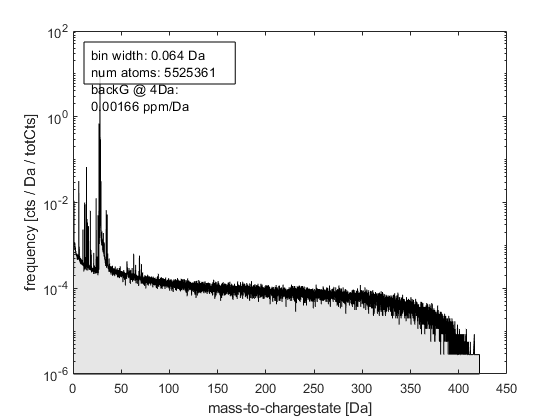

Error using matlab.graphics.interaction.webmodes.toggleMode
Unknown action character vector.

Error in matlab.graphics.interaction.webmodes.modeHelper

Error in matlab.graphics.interaction.webmodes.modeFunctionHelper

Error in matlab.graphics.interaction.webmodes.panWeb

Error in pan (line 206)
            matlab.graphics.interaction.webmodes.panWeb(arg1, []);

Error in massSpecPlot (

spec = massSpecPlot(pos,bin,mode); % plots the mass spectrum

The plotted mass spectrum can be ranged in two possible ways.

## Adding ions with knowledge of occurring ions

With the function ionAdd, you can easily add stem plots of ions. Therefore, several input variables are necessary. The first input variable is the mass spectrum (spec), in which the ion stem plot will be plotted. For the definition of the wanted ion, the name of the corresponding atom, the charge state (also as a vector of several charge states possible), the margin within which two peaks will be summed up, and the minimal abundance need to be defined. Optionally, the height of the most abundant isotope, which can be chosen either as 'selection' or 'most abundant', and the maximal seperation of two peaks (maxSeparation) can be specified.

% please execute the following command in your command line: spec = massSpecPlot(pos,bin,mode);
% and proceed with:
ion = 'Fe' % chemical symbol of the ion that will be added
chargeState = 2 % charge state of the ion, vector of charge states
sumMargin = 0 % specifies a margin within which two peaks will be summed up
minAbundance = 0 % is the minimal abundance
maxHeight = 'most abundant' % is the height of the most abundant isotope
maxSeparation = 0.1 % the maximum of the mass spectrum within this range will be used for scaling

ionAdd(spec,ion,chargeState,isotopeTable,colorScheme,sumMargin,minAbundance,maxHeight,maxSeparation) % ionAdd creates a stem plot in the mass spectrum (spec) for the parsed ion and its corresponding charge state(s)

 

For deleting ion stem plots, just click on them with the cursor in *Edit Plot* and press delete.

## Adding ions without knowledge of occurring ions

If you do not know which ions were detected, the function ionFind will be of much help. To execute this function, you first have to create an ionTable which contains all possible ions (ionTableCreate). As inputs for this function, you have to choose if 'all' or only specified elements come into question. Additionally, the wanted charge states, the maximal complexity of the (molecular) ions, the complex formers, and the abundance threshold need to be defined.

elements = 'all' % can be a list of atomic numbers, symbols or 'all'
chargeStates = [1 2 3] % array of charge states
maxComplexity = 2 %  maximal complexity of the created ions
complexFormers = 'std' %  if complex formers is set to 'std', the complex formers are H, H2, H3, C, C2, C3, N, O, O2. 
% If complexFormers = 'and C P ....' it takes the standard ('std') elements and adds the additional specified elements
abundanceThreshold = 0.01 % sets an threshold for used isotopes to build the list
ionTable = ionTableCreate(elements,chargeStates,isotopeTable,maxComplexity,complexFormers,abundanceThreshold);
 

After creating the ionTable, the addition of ion stem plots can be done with the ionFind function. Therefore, you need to execute the function and then click on the wanted peak. A pop-up window will appear, that indicates possible ions that matches to the selected peak. You can then choose the most suitable entry from the list.

searchRange = 0.15% range in which suggested ions would have a peak
ionFind(spec,ionTable,isotopeTable,colorScheme,searchRange);
 

## Step-by-step ranging of the added ions

Subsequently, ranges of the defined ions can be added in the mass spectrum. With rangeAdd, you can add ranges one by one. As input variables only the mass spectrum and the colorScheme are needed. Partial or total overlaps with already existing ranges are reported. 

rangeAdd(spec,colorScheme); % the user can manually range the mass spectrum
 

## Automated ranging of the added ions

If the user don't want to execute the rangeAdd function all the time you only have to 